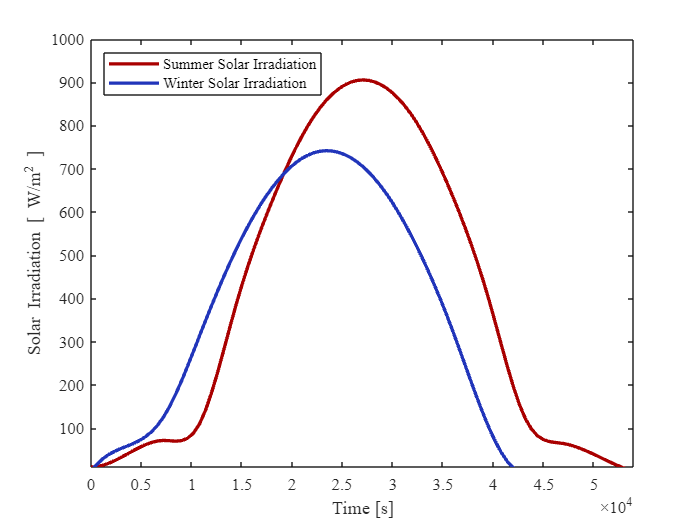

% out = sim("Summer_Controlled.slx")
% 
% totaldata = out.VoltageSummer;
% 
% time = out.VoltageSummer.signals(2).values;
% voltage = out.VoltageSummer.signals(1).values;




% plot(time,voltage,LineWidth=2,Color='#D95319')
% legend('Motor Input Voltage','Location','northwest')
% xlabel('Time [s]')
% ylabel('Voltage [V]')
% fontname('Times New Roman',11)
% hold on

x = [0 3600 7200 10800 14400 18000 21600 25200 28800 32400 36000 39600 43200 ];
y = [0 58.53658537 125.14634146 313.7560976 511.6097561 655.6097561 731.7073171 732.8780488 660.2926829 519.804878 323.1219512 99.51219512 0];
xx = 0:600:43200;
irr = spline(x,y,xx);

xs = [0 3600 7200 10800 14400 18000 21600 25200 28800 32400 36000 39600 43200 46800 50400 54000];
ys = [10 40.0195122 71.46341463 110.0536585 383.0439024 624.5902439 800.3902439 893.2926829 894.7219512 806.1073171 634.595122 394.4780488 121.4878049 65 35 0];
xxs = 0:600:54000;
irrs = spline(xs,ys,xxs);

% plots WInter Irradiation
plot(xxs,irrs,LineWidth=2,Color='#a90000')
hold on
plot(xx,irr,LineWidth=2,Color='#2135ba')
legend('Summer Solar Irradiation','Winter Solar Irradiation','Location','northwest')
xlabel('Time [s]')
ylabel('Solar Irradiation [ W/m^2 ]')
fontname('Times New Roman',11)
ylim([10 1000])
xlim([0 54000])
hold on



% plots Summer>Non-Linear>Controller vs Uncontrolled
% subplot(1,2,2);
% plot(Summer_time,Summer_sundata,LineWidth=3,Color='#D95319')
% hold on
% plot(Summer_time,Summer_Cont_nonlinear,LineWidth=2,LineStyle="--",Color='#00FFFF')
% hold on
% plot(Summer_time,Summer_Uncont_nonlincear,LineWidth=2,LineStyle="--",Color='#77AC30')
% legend('Sun Azimuth Position','Controlled Response','Uncontrolled Response','Location','northwest')
% title('Linear System')
% xlabel({'Time [s]'; ''})
% ylabel('Azimuth Angle [deg]')
% fontname('Times New Roman',11)
% hold off


